% simplificao de um sistema de segunda ordem
% considerando como um ganho constante
wn = 10;
zeta = 0.7;
G = tf(wn^2,[1 2*zeta*wn wn^2])

G =
 
        100
  ----------------
  s^2 + 14 s + 100
 
Continuous-time transfer function.
Model Properties


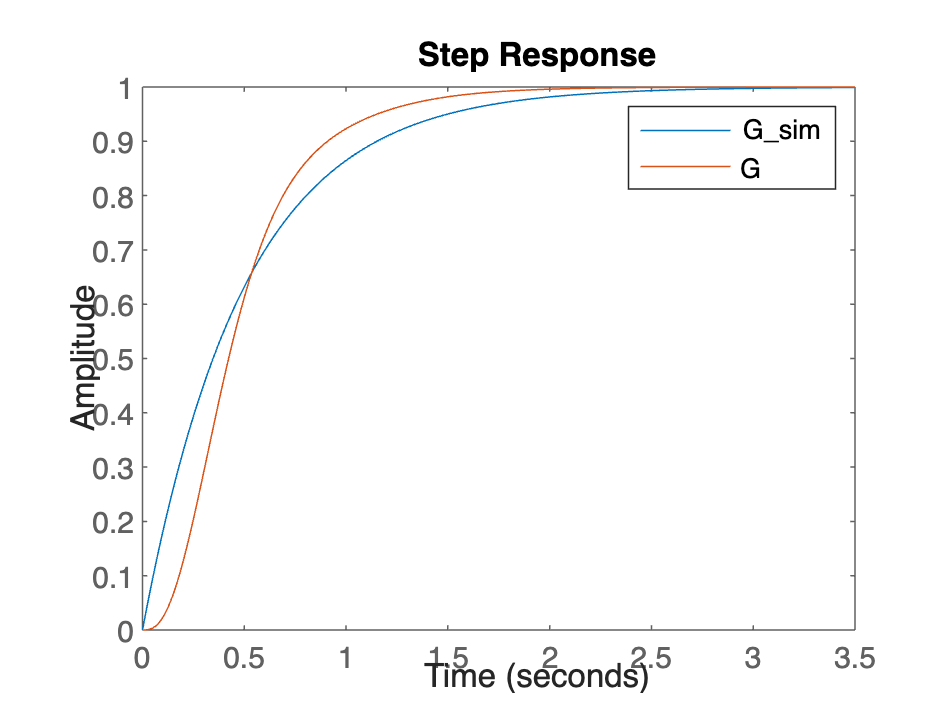


% vamos simplificar como um sistema de ganho constante
G_sim = 1;
Ki = 2;
C = Ki * tf(1,[1 0]);
figure;
step(G_sim*C/(1+G_sim*C)); hold all;
%vamos testar no sistema original (nao simplificado)
step(G*C/(1+G*C)); legend('G_sim', 'G')

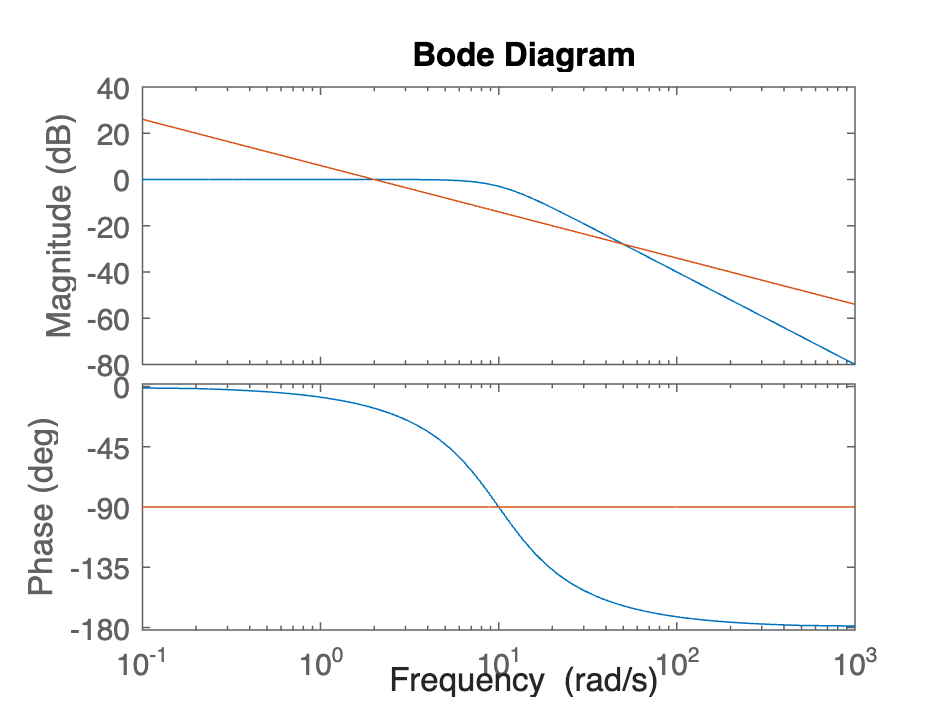

figure; 
bode(G); hold all;
bode(C)

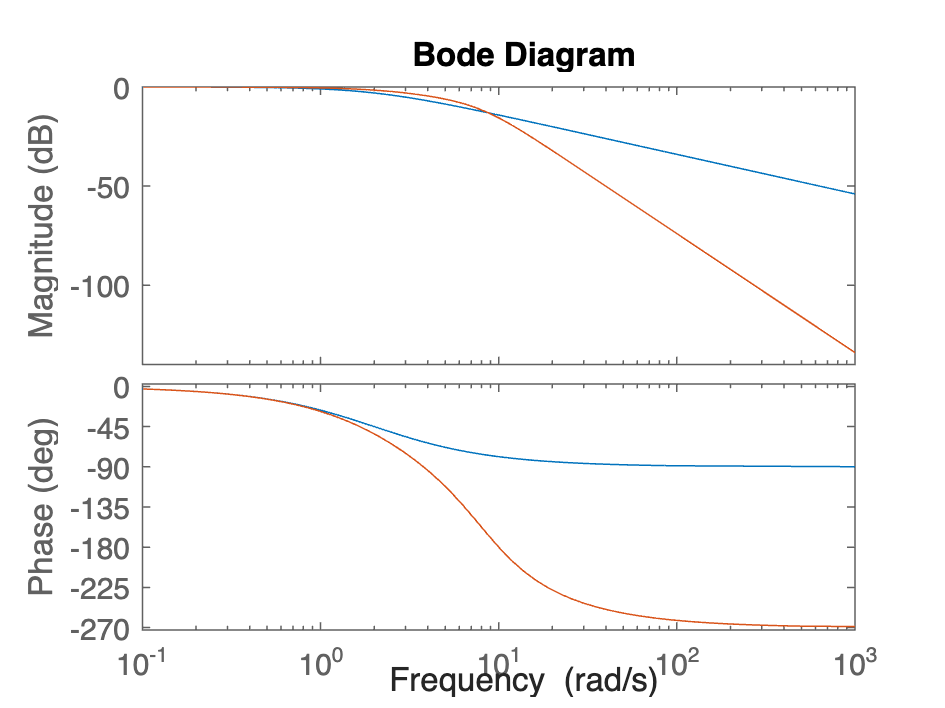


figure;
bode(G_sim*C/(1+G_sim*C)); hold all;
bode(G*C/(1+G*C));